# Insect Population

**skills: **difference equations, for loops

In the following guided exercise, we will use finite difference equations to create a simple model of a population of insects.

## Intro

We will use one generation as the unit of time here even though the life cycle of insects are generally more complex and each stage may take weeks to years.

Here, we consider the reproduction of the poplar gall aphid. Adult female aphids produce *galls* on the leaves of poplars, like the ones in the picture below:

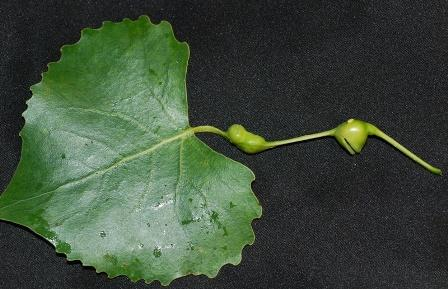source: [https://www.gov.mb.ca/agriculture/crops/insects/poplar-petiole-gall-aphid.html](https://www.gov.mb.ca/agriculture/crops/insects/poplar-petiole-gall-aphid.html)

Each gall contains all the progeny of a single aphid, and a fraction of these survive to adulthood and reproduction stage.

The capacity for producing offspring (fecundity) and the likelihood of surviving to adulthood (survivorship) depend on a variety of conditions. 

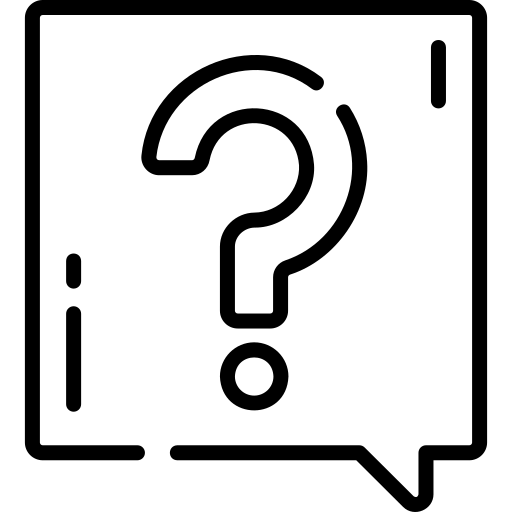Q0: Can you guess what factors may affect survivorship?

  answersQ0

However, we are going to ignore these effects for this exercise, and write a simple model.

 Definitions

We are going to need the following definitions:

- `a(n) `or $a_n$ denotes the number of adult female aphids in the nth generation

- `p(n) `or $p_n$ denotes the number of progeny in the nth generation

- `m` denotes the fractional mortality of the young aphids (the fraction that die before maturity)

- `f` denotes the number of progeny per female aphid

- `r` denotes the ratio of female aphids to total aphids

 Q1: what's the fraction of aphids that survive into adulthood? (hint: in terms of m)

## Difference Equations

Before we get to the MATLAB code, let's discuss how we can write our model given the definitions above. 

#### The goal

We want to end up with an equation that tells us how many adults are in generation n+1 given that we know there are a_n adults in generation n. For example, if we know that there are 20 adults in the first generation, the equation would predict the number of adults in the second generation. 

 Q2: How is $p_{{\;}_{n+1} } \;$related to $a_n$? What parameter do we need here? This is equation 1.

 Q3: How is $a_{{\;}_{n+1} } \;$related to $p_{n+1}$? What parameter do we need here? This is equation 2.

 Q4: How is $a_{{\;}_{n+1} } \;$related to $a_n$? Combine equations 1 and 2 to get this equation.

## Variable Set-Up

Now, we set up the variables and parameters that we need:

n is the integer denoting the generation of our interest and f the number of progeny per female, and a0 is the number of adults at the first generation:

n = 4;
f = 5;
a0 = 200;

`a and p` contain the number of adult female aphids and of progeny in each generation up to the nth, respectively:

a = zeros(n,1);
p = zeros(n,1);

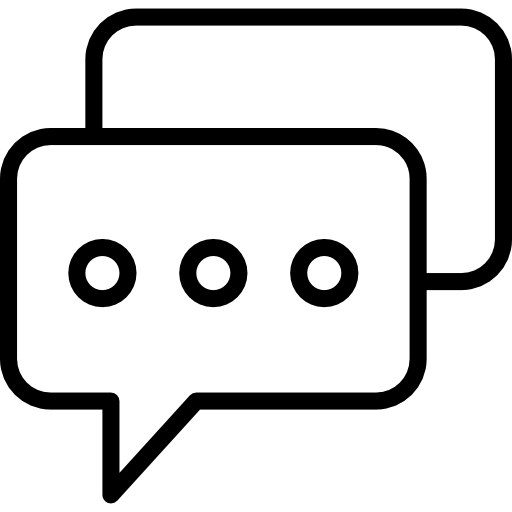 Here, we are *initializing* `a` and `p` as *arrays*, or sets. Think about the reasoning behind why we are making this choice.

m is a fraction that helps us calculate how many young aphids survive to reproduction stage and r the ratio of female aphids:

m =0.5;
r =0.5;

Q6: What is the range of values that m and r can take?

Since calculating the population at each generation depends on the information from the previous generation, we use a for loop here. But first, we set the initial value of `a` using the initial population, `a(1) = f*r*(1-m)*a0`.

a(1) = f*r*(1-m)*a0;

for i = 2:n

    a(i) = f*r*(1-m)*a(i-1);

end

We can now create a plot: 

generations = 1:n;
plot(generations, a,'k*','LineWidth',3, 'DisplayName','from the for loop')
xlabel('generation')
ylabel('number of adults')


Let's check whether the number of adults in generation n agrees with what we learned last time. Last time, we said we can write equation 3 in the following form:

$a_n ={\left\lbrack f\;r\;\left(1-m\right)\right\rbrack }^n a_0$    equation (4)

or

a_n = a0*(f*r*(1-m))^n
a(n)

This exercise was paraphrased from Mathematical Models in Biology by Dr. Edelestein-Keshet.

## Answers to Questions

- 
$$1-m$$


- 
$$p_{n+1} =f\;a_{n\;}$$


- 
$$a_{n+1} =r\left(1-m\right)\;p_{n+1\;}$$


- 
$$a_{n+1} =f\;r\left(1-m\right)\;a_n$$


- Between 0 and 1

function answer1 =answersQ0()

answer1 = 'enviornmental conditions, the food available, population size';

end